x_noisy =    -2.0113   -0.1803   -1.3098   -1.1563   -2.1891   -0.9380   -2.5271   -1.5866    1.0593   -1.3062   -0.3594   -1.0630   -0.9008   -1.0826   -2.2986   -0.4205   -2.1954   -2.3342   -2.0891   -0.5495    1.0120   -1.7169   -0.6074   -0.7124   -2.0092    0.7070   -1.0976    0.6328    2.0813   -1.0125    0.3242   -1.9767    0.4173    0.5934   -0.1065    1.2144   -0.2488   -1.3826   -1.7663   -1.4809   -0.3419   -0.4406    0.7589   -0.2002   -1.6114    0.4375   -0.8221   -1.0617   -0.6692   -1.1207
   -0.3237   -1.3024   -1.8044   -1.9276    0.6821   -0.1143    0.8568   -0.9347    0.6149   -1.1702    0.7296   -1.8483    0.4847   -0.3169   -1.9255   -0.2935   -0.6609   -1.3870    0.7459   -1.0595   -2.6318   -2.3108   -0.3830   -1.9755    0.0790   -1.9492    1.0690    0.6087    1.6704   -0.9497   -1.8445    1.6414    0.1141   -0.0595    0.4232   -0.7514   -0.0620   -1.5058   -2.6121   -0.6661   -0.8451    1.6582   -0.8253    0.7831   -1.2047   -1.6481   -0.2964   -0.3967   -1.169

alpha = 0.7880

signal_entry_est = 1×6000 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


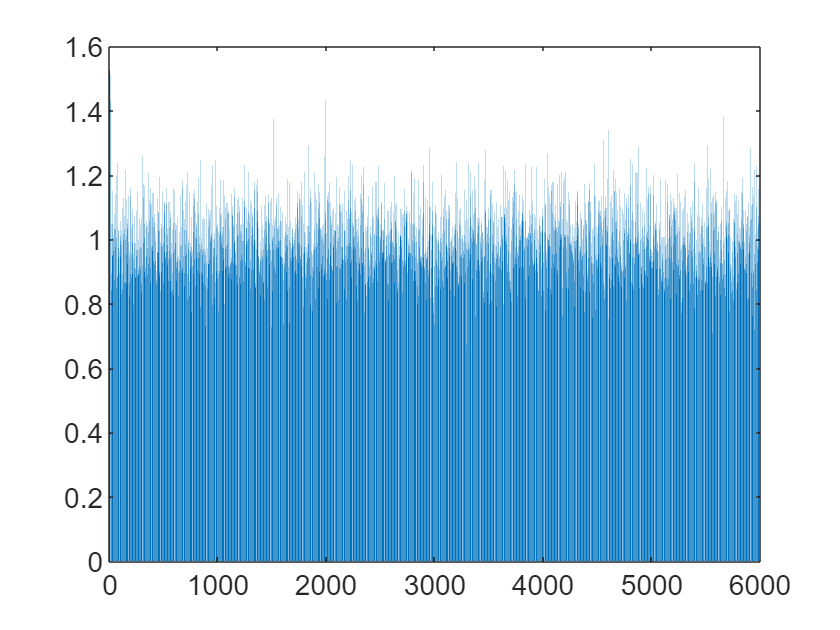

obj =   variance_test_spectral with properties:

                   X: [6000×200 double]
                   K: 2
                   n: 200
                   p: 6000
                 var: [1.4714 1.5858 1.5267 1.3593 1.5052 1.2773 1.2913 1.4288 1.3934 1.5154 0.8815 1.0211 1.1393 0.9714 0.8947 0.9692 0.8416 0.9833 0.9664 0.8374 0.9113 1.0480 1.0176 1.0470 0.9550 0.9478 1.1449 1.1082 1.1520 0.9223 … ] (1×6000 double)
             var_min: 0.6728
               alpha: []
            acc_dict: []
    cluster_est_dict: []
    signal_entry_est: []
         x_tilde_est: []
      omega_est_time: []
      sdp_solve_time: []
    entries_survived: []
        obj_val_prim: []
        obj_val_dual: []
    obj_val_original: []


Unrecognized function or variable 'n'.

Error in variance_test_spectral/get_signal_entry_est (line 50)
            alpha = sqrt(6 * ( log_np / n)) + (2 * log_np / n);

Error in variance_test_spectral/fit_predict (line 61)
            obj.get_signal_entry_est();

ans = 1×6000 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


p=6000;
n=200;
sigma = 1;
K=2;
rounding = 1e-4;
cluster_true = [repelem(1,n/2), repelem(2,n/2)];

sep =12;
s = 10;
M = 0.5*sep/sqrt(s);
sparse_mean = [repelem(1,s), repelem(0,p-s)];
mu_1 =  -M * sparse_mean;
mu_2 =   M * sparse_mean;
x_noiseless = [ repmat(mu_1, n/2,1); repmat(mu_2, n/2,1) ];
tic
x_noisy = x_noiseless+ sigma^2 * randn(n, p); %data generation
x_noisy = x_noisy'

x_noisy =    -1.5118   -1.0334   -3.1638   -1.1435   -0.7575   -1.0417   -0.5649   -1.3422   -2.0940   -3.7714   -1.6163   -3.6113   -1.3978   -1.4383   -1.9405   -2.2189   -1.7381   -2.9914   -2.0560   -3.2836   -0.3942   -1.0217   -3.9917   -3.3926   -2.4298   -1.5748   -1.6358   -1.8843   -1.0148   -1.9298   -0.6318   -2.6846   -1.7745   -1.7705   -2.7508   -2.5699   -2.6390   -0.5530   -2.5660   -1.5693   -1.6262   -3.2105   -1.2546   -2.4549   -1.3927   -2.3280   -0.7598   -0.8044   -2.0854   -2.2094
   -1.8739   -1.7463   -1.9469   -3.6019   -2.7093   -2.4591   -2.6741   -2.2540   -1.5937   -1.6168   -1.0354   -2.2655   -1.2806   -2.6395   -3.7291   -2.2066   -0.3659   -2.0384   -0.9424   -2.0811   -2.4184   -2.8220   -2.0250   -1.7736   -2.5612   -3.4987   -3.4006   -2.9622   -1.9709   -2.1160   -2.1746   -1.7686   -0.7943   -1.2816   -0.1179   -2.6354   -3.8466   -1.7809   -1.0593   -1.6258   -1.5121   -2.0958   -1.8172   -1.8044   -1.1978   -1.7265   -1.6860   -1.1281   -1.903

learner  = variance_test_spectral(x_noisy);
sum(learner.get_signal_entry_est)

ans = 1

learner.signal_entry_est